syms x;
f(x) = exp(x);
R11(x) = simplify(pade_approximant(f, 1, 1, x))

$$R11(x) = -\frac{\frac{x}{2}+1}{\frac{x}{2}-1}$$

R22(x) = simplify(pade_approximant(f, 2, 2, x))

$$R22(x) = \frac{\frac{x^{2}}{12}+\frac{x}{2}+1}{\frac{x^{2}}{12}-\frac{x}{2}+1}$$

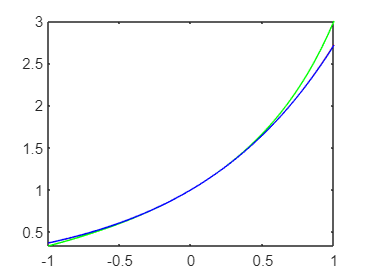


figure();
fplot(f, [-1, 1], 'Color', 'red');
hold on;
fplot(R11, [-1, 1], 'Color', 'green');
fplot(R22, [-1, 1], 'Color', 'blue');

Aceste aproximari rationale sunt satisfacatoare pe [-1, 1], fiind foarte apropiate ca valori.

g(x) = log(1 + x);
R22(x) = simplify(pade_approximant(g, 2, 2, x))

$$R22(x) = \frac{3\,x\,\left(x+2\right)}{x^{2}+6\,x+6}$$

R31(x) = simplify(pade_approximant(g, 3, 1, x))

$$R31(x) = \frac{-\frac{x^{3}}{24}+\frac{x^{2}}{4}+x}{\frac{3\,x}{4}+1}$$

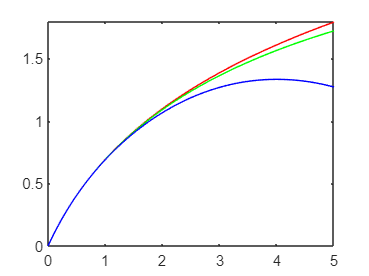


figure();
fplot(g, [0, 5], 'Color', 'red');
hold on;
fplot(R22, [0, 5], 'Color', 'green');
fplot(R31, [0, 5],'Color', 'blue');